#  Antiderivadas 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

Las tasas de cambio de las variables aparecen con frecuencia cuando se estudian interacciones de la vida real, incluidas la velocidad, la aceleración y la corriente. En los casos en los que conocemos la derivada y queremos determinar la función original, queremos encontrar la * antiderivada. *

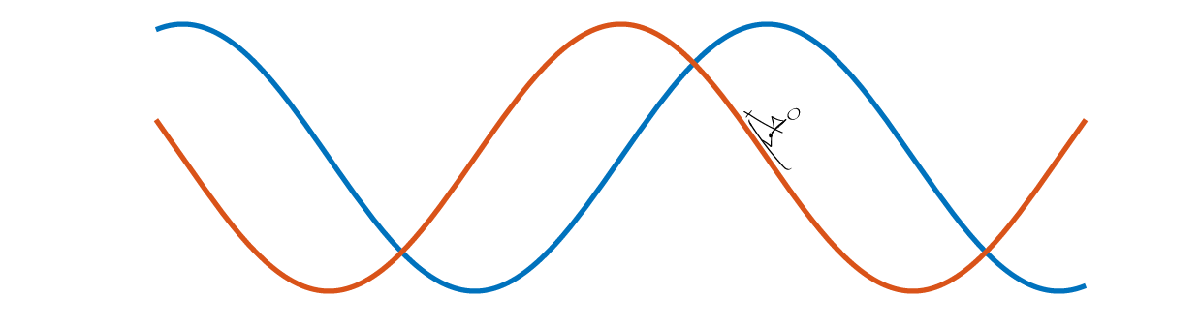

Utilizando el conocimiento de las derivadas, es posible definir una operación que deshará una derivada. 

**Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña **View **de la barra de herramientas de MATLAB, en la sección ** View **, selecciona **Hide Code**.  Alternativamente, selecciona **Hide Code **usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesitas más instrucción, considera realizar el [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

##  Familias de antiderivadas 

$\displaystyle\int f(x) \; dx = F(x) +C,$ para cualquier constante $C$

f = @(x) sin(x);
 
xVals = -5:.02:5;
syms x
F(x) = int(f,x);
figure
pfC = DrawFamily(xVals,F(xVals)); 

Para seleccionar un elemento particular de la familia, elige un valor de $C$. 

C = 0; 
ani = false;
if ~exist("pfC","var")
    xVals = -5:.02:5;
    syms x
    f(x) = sin(x); % Configuración de valores predeterminados
    F(x) = int(f,x);
    figure
    pfC = DrawFamily(xVals,F(xVals));
end
if ani
    % Identify maximum and minimum values range of plotted family members to
    % determine a reasonable window
    Fx = double(F(xVals)); 
    FxMin = min(Fx);
    FxMax = max(Fx);
    pfC.Parent.YLim = [FxMin FxMax] + [-10 10];

    % animar la trama
    for C = [-10:.25:10 10:-.25:-10]
        pfC.YData = Fx + C;
        subtitle(pfC.Parent,"$C = $"+C,"Interpreter","latex");
        drawnow
    end
else
    pfC.YData = F(xVals)+C; 
    subtitle(pfC.Parent,"$C = $"+C,"Interpreter","latex");
end
drawnow

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

Si deseas ver los detalles del código, selecciona la pestaña **View** y selecciona **Output inline**. Como alternativa, selecciona **Output inline** usando el ícono   en la parte superior derecha del panel Live Editor. 

function pfC = DrawFamily(xVals,FxVals)
try
    pf = plot(xVals,FxVals,"LineWidth",3,SeriesIndex="none");
catch
    pf = plot(xVals,FxVals,"k","LineWidth",3);
end
    hold on
    pfC = copyobj(pf,pf.Parent);
    pfC.Color = [1 0 0];
    pfC.Parent.YLim = [min(double(FxVals))-8 max(double(FxVals))+8];
    Copts = [-10:.5:-.5 .5:.5:10];
    FVals = FxVals+Copts';
    plot(pf.Parent,xVals,FVals,"LineWidth",1,SeriesIndex=1);
    hold off
title("Trazado de la familia de antiderivadas $F(x)+C$","Interpreter","latex")
pfC = copyobj(pf,pf.Parent);
pfC.Color = [1 0 0];
legend(pf.Parent,["F(x)" "Familia de F(x)" "F(x)+C"],"Location","bestoutside")
end

% Suppress warning message about unreachable code behind live controls
%#ok<*UNRCH>
